load("./data/project_data.mat")

Fs = 30 kHz

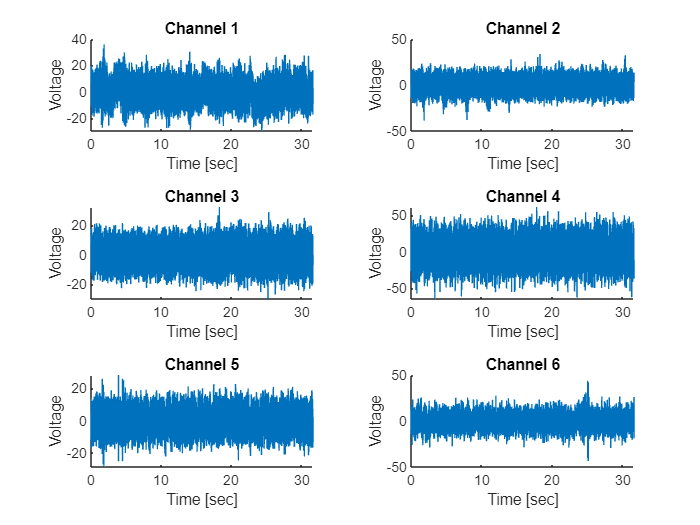

t = (1:length(unfilteredNeuralData))'/30e3;
tlo = tiledlayout('flow');

for channel = 1:6
nexttile; plot(t, unfilteredNeuralData(:,channel))
ylabel("Voltage")
xlabel("Time [sec]")
title(sprintf("Channel %d", channel))
box off
end

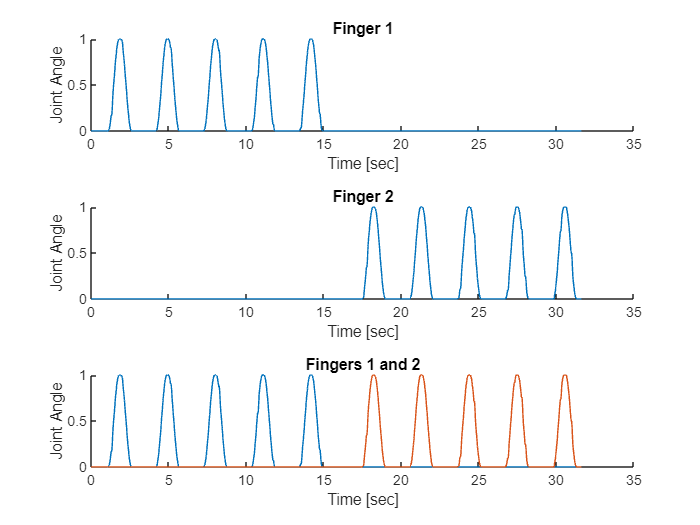

tlo = tiledlayout(3,1);
for finger=1:2
nexttile; plot(t, Kinematics(:,finger))
ylabel("Joint Angle")
xlabel("Time [sec]")
title(sprintf("Finger %d", finger))
box off
end
nexttile; plot(t, Kinematics)
ylabel("Joint Angle")
xlabel("Time [sec]")
title("Fingers 1 and 2")
box off

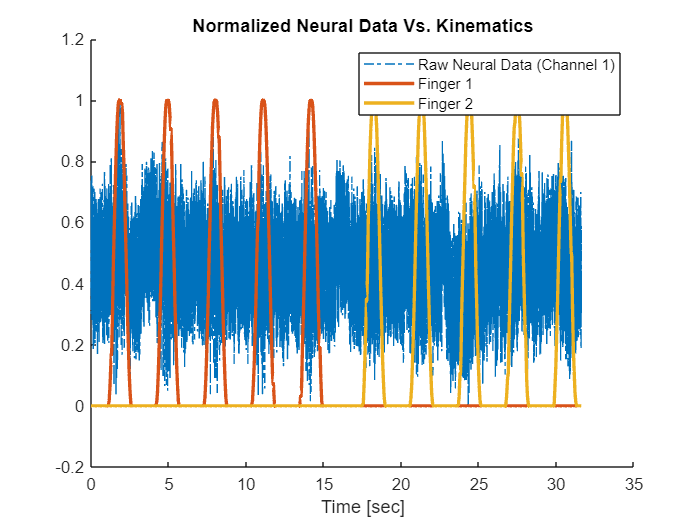

figure
plot(t, normalize(unfilteredNeuralData(:,1), "range"), '-.');
hold on
plot(t, Kinematics, LineWidth=2)
hold off
box off
xlabel("Time [sec]")
title("Normalized Neural Data Vs. Kinematics")
legend({"Raw Neural Data (Channel 1)", "Finger 1", "Finger 2"})